#  Reglas de derivadas para potencias 

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

La definición de límite básico de la derivada puede ser lenta y difícil de aplicar. Para la mayoría de las funciones estándar, es más fácil probar algunas reglas para funciones simples y luego calcular derivadas complicadas dividiendo las funciones en partes simples que se ajusten a las reglas conocidas. 

**Antes de comenzar: **

Este live script está diseñado para usarse con el código oculto. En la pestaña ** View **de la barra de herramientas de MATLAB, en la sección ** View**, selecciona **Hide Code**. Alternativamente, selecciona **Hide Code **usando el ícono   en la parte superior derecha del panel Live Editor. 

 Aunque el código está oculto, cierta interactividad requiere familiaridad con MATLAB. Si necesitas más instrucción, considera realizar [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea gratuito de 2 horas que enseña los conceptos básicos de MATLAB. 

 Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pasa a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si ejecutan en el orden incorrecto. 

 Este script se basa en la definición de límite de la derivada, como se analiza en [Definition.mlx](matlab:open('./Definición.mlx')). 

##  Regla de potencia 

Un tipo de función simple son las funciones de potencia: $y = x^n$. La siguiente sección calcula la derivada de potencias enteras positivas utilizando el cociente de diferencias. 

Recuerda que una función lineal se presenta en la forma estándar $y = mx+b$ donde $m$ es la pendiente y $b$ es la intersección $y$. Dado que las pendientes son derivadas, esto significa que la derivada de $y=mx+b$ debe ser $m$. Observa que: 

$\frac{dy}{dx} = \lim_{h\to 0} \frac{(m(x+h)+b)-(mx+b)}{h} = \lim_{h\to 0}\frac{(mx+mh+b)-(mx+b)}{h} = \lim_{h\to 0} \frac{mh}{h} = \lim_{h\to 0} m = m$. 

Este resultado sigue siendo válido en el caso especial de una función constante con $m=0$ que se describe mediante $y=b$. El poder del cálculo reside en su capacidad para describir la pendiente de curvas y líneas rectas. 

###  Ejemplo: Derivada de una cuadrática 

Sea $y(x) = x^2$. Aplicando [definición límite de la derivada](matlab:open('./Definition.mlx')) , calculamos que 


$$\frac{dy}{dx} = \lim_{h \to 0} \frac{y(x+h)-y(x)}{h}$$
        


$$\frac{dy}{dx} = \lim_{h\to 0} \frac{(x+h)^2-x^2}{h}$$
            


$$\frac{dy}{dx} = \lim_{h\to 0} \frac{(x^2+2xh+h^2)-x^2}{h}$$



$$\frac{dy}{dx} = \lim_{h\to 0} \frac{2xh+h^2}{h}$$
                 


$$\frac{dy}{dx} = \lim_{h\to 0} 2x+h$$
                    


$$\frac{dy}{dx} = 2x$$
                               

Una forma de verificar la derivada es usarla para graficar la recta tangente a la función en varios puntos. Recuerda que la línea tangente es la línea recta que pasa por un punto dado en la gráfica, digamos $(a,f(a)) = (a, a^2)$ con la misma pendiente, es decir, derivada, que la función misma en ese punto que es $f'(a) = 2a$. Dada la derivada calculada anteriormente, hay una línea tangente que pasa por $x=a$ descrita por: 


$$y = f(a) + f'(a)(x-a)$$
                                       

$y = a^2+2a(x-a)$ o, simplificado $y=2ax-a^2$.

Graficar la función y la línea tangente a la función permite una verificación visual rápida de la precisión del cálculo de la derivada. 

syms x         % Crear una variable simbólica
a =0;       % Solicitar entrada del usuario para seleccionar un punto
if ~exist("drpHandle","var") || ~isvalid(drpHandle)
    % este código solo se ejecuta la primera vez que se ejecuta esta sección
    f(x) = x^2;    % Definir f(x) como una función simbólica
    figure         % Inicializar una figura
    fplot(f)     % Trazar simbólicamente y=x^2
    ylim([-1 25])  % Amplíe la ventana del gráfico para ver mejor el vértice del gráfico.
    title("$y=x^2$ y la línea tangente $y=2ax-a^2$ en $x=a$","Interpreter","latex")
    xlabel("x")    % Etiqueta el eje x
    ylabel("y(x)") % Etiqueta el eje y
    hold on
    ya = double(f(a));                    % Calcular f(a) como un número
    drpS1 = scatter(a,ya,"filled",SeriesIndex=2);   % Añade un punto en (a,f(a))
    [~,linApprox] = GetLinApprox(f,x,a);  % La función getLin Aprox está definida en Funciones auxiliares locales.
    drpHandle = plot([a-2,a+2],linApprox([a-2,a+2]),"LineWidth",2,SeriesIndex=3); % Color nuevo
    hold off
end
drpS1.XData = a;                      % Restablecer la coordenada x del punto
drpS1.YData = f(a);                   % Restablecer la coordenada y del punto
drpHandle.XData = [a-2,a+2];          % Restablecer los datos x para la aproximación lineal
[m,tanApprox] = GetLinApprox(f,x,a);  % La función getLin Aprox está definida en Funciones auxiliares locales.
drpHandle.YData = tanApprox([a-2,a+2]); % Restablecer los datos y para la aproximación lineal
legend(["$f(x)$" "$(a,f(a))$ = (" + a + "," + double(f(a)) + ")" ...
    "línea tangente con pendiente " + m],"Location","north","Interpreter","latex")
 

  ** Inténtalo. ** Mueve el control deslizante a diferentes valores y observa cómo varía la pendiente de la recta tangente en diferentes puntos. ¿Coincide con el valor calculado algebraicamente? 

** Ejercicio 1**. Utilizando la definición de límite de la derivada, calcule ls derivada $\frac{dy}{dx$ para $y(x) = x^3$. 

  ** Consejo**. La sintaxis de MATLAB es 7 `*x^2` para $7x^2$ o `exp(-2*x)` para $e^{-2x}$. Para obtener más detalles, consults la documentación del centro de ayuda para [funciones matemáticas](https://www.mathworks.com/help/matlab/referencelist.html?type=function&listtype=cat&category=mathematics) o [referencia de funciones básicas](https://www.mathworks.com/content/dam/mathworks/fact-sheet/matlab-basic-functions-reference.pdf). 

syms x
MyAnswer = 1* x^3;
 
disp("My answer is:")
displayFormula("dy/dx = MyAnswer")
CheckEx1(MyAnswer)

###  Identificación de la regla de la potencia 

Los cálculos involucrados en el cálculo de la derivada de una potencia a partir de la definición límite de la derivada se complican más rápidamente a medida que la potencia aumenta. Esta sección implementa los mismos cálculos con los que trabajaste anteriormente para permitir probar varias potencis fácilmente para buscar patrones en los resultados. 

  ** Inténtalo. ** Elige una potencia de $n$ para ejecutar los siguientes cálculos para calcular la derivada $\frac{d}{dx}\left[x^n\right]$ : 

syms x h                       % Definir variables simbólicas
                % Ejecute esta sección
n = 6  % Seleccione la potencia entera positiva deseada
f(x) = x^n;                    % Definir una función simbólica f(x) = x^n
oldPrefs = sympref();          % Guarde las preferencias del usuario actual para restablecerlas al final de la sección
sympref('PolynomialDisplayStyle','descend');  % Presentar polinomios en formato de potencia descendente.
sympref('FloatingPointOutput',false);         % No utilice representaciones de punto flotante
fxhD = f(x+h);                 % Nombra la función simbólica f(x+h) 

Evalua: 

displayFormula("f(x+h) = fxhD") % Mostrar la fórmula
% Utilice la aproximación polinómica de Taylor incorporada para expandir el polinomio
fxph(x,h) = taylor(f(x+h),x, "ExpansionPoint",0, "Order", 11);
fxphD = fxph(x,h);                    % Nombra la función simbólica
displayFormula("f(x+h) = fxphD")      % Mostrar la fórmula

Calcular el cociente de diferencias: 

DQ = (fxph - f(x))/h;                  % Nombra el cociente de diferencias simbólicas.
displayFormula("(f(x+h)-f(x))/h = DQ") % Mostrar la fórmula 

Simplificar el cociente de diferencias: 

DQsimplified = simplify(DQ(x,h));      % Nombra el cociente de diferencias simbólico simplificado.
displayFormula("(f(x+h)-f(x))/h = DQsimplified") % Mostrar la fórmula 

Calcular el límite del cociente de diferencias como $h$ se aproxima a 0: 

displayFormula("df/dx = limit((f(x+h)-f(x))/h,h,0)")
displayFormula("df/dx = limit(DQsimplified,h,0)")
limDQ = limit(simplify((f(x+h)-f(x))/h),h,0);  % Nombra el límite del cociente de diferencias simplificado.
displayFormula("df/dx = limDQ")                % Mostrar la fórmula resultante
sympref(oldPrefs);   % Restaure las preferencias del sistema que tenía antes de ejecutar este script.

 ** Reflexiona ** ¿Puedes encontrar un patrón en los resultados $\frac{df}{dx}$ para diferentes valores de $n$ ? 

** Ejercicio 2**. Para un entero positivo $n$, ¿puedes escribir una regla para la derivada? 

Si $f(x) = x^n$ , entonces $\frac{df}{dx}$ = ? 

syms x n                      % Definir variables simbólicas
dfdx =  x^n;  % Asignar una función definida por el usuario a dfdx
CheckPwrRule(dfdx,x,n);           % checkPwrRule está definido en Funciones auxiliares locales
% checkPwrRule compares dfdx to the correct power rule and displays
% feedback
                   % Ejecute esta sección

###  Ampliando la regla de la potencia 

¿Qué sucede si $n$ no es un entero positivo? Si $n=0$ esto es bastante factible a mano, pero ¿qué pasa con otros valores? ¿Tu regla todavía funciona? 

syms x h                                      % Definir variables simbólicas
oldPrefs = sympref();                         % Guarde las preferencias actuales para restaurarlas al final de la sección
sympref('PolynomialDisplayStyle','descend');  % Presentar polinomios en formato de potencia descendente.
sympref('FloatingPointOutput',false);         % No utilice representaciones de punto flotante
n = 0.5                      % Seleccionar y mostrar una potencia n
order = 5             % Seleccione un orden para usar en la aproximación de Taylor
                                % Ejecute esta sección
f(x) = x^n                                    % Definir una función simbólica f(x) = x^n
fxph(x,h) = f(x+h);                           % Cree una función multivariable para usar en la expansión de Taylor
% La definición de DQ usa simplificar el cociente de diferencias para
% eliminar los factores comunes en la expresión racional y expandirse para
% dividir en términos reconocibles
DQ = expand(simplify((taylor(fxph,h,"Order",order)-f(x))/h));
displayFormula("f(x+h) = DQ")
displayFormula("df/dx = limit((f(x+h)-f(x))/h,h,0)") % límite es una función simbólica de MATLAB
DQ0 = DQ(x,0);                                % Nombra el cociente de diferencias evaluado.
displayFormula("df/dx = limit(DQ,h,0)")
displayFormula("df/dx = DQ0")
sympref(oldPrefs);   % Restaure las preferencias del sistema que tenía antes de ejecutar este script.

  ** Consejo**. El método utilizado para aproximar el cociente de diferencias aquí se llama [Serie Taylor](https://www.mathworks.com/help/symbolic/sym.taylor.html#busozb7-8). Este es un método extremadamente útil que probablemente volverás a ver. Cuanto mayor sea el orden, más cerca estará la aproximación de su función original. ¿Qué impacto tiene cambiar el orden en tu cálculo? 

** Ejercicio 3. **

Calcula la derivada de las siguientes expresiones a mano usando la regla de la potencia: 

- 
$$x^2$$
 

- 
$$x^{-2}$$


- 
$$x^{1/2$$


- 
$$3$$


pwrRuleSelected = false;     % Esto establece un valor booleano para controlar mostrar/ocultar las soluciones.
if pwrRuleSelected
    syms x; %#ok<*UNRCH>
    disp("3.1. ")
    ans1 = 2*x
    disp("3.2. ")
    ans2 = -2*x
    disp("3.3. ")
    ans3 = 1/2*x^(-1/2)
    disp("3.4. ")
    ans4 = 0
    disp("Nota: Esto se puede considerar como una regla de potencia en términos de x^0," + newline + ...
         "      pero a veces se llama la Regla Constante.")
    disp("      ¡La derivada de cualquier constante es cero!")
end

##  Reglas de linealidad 

El problema con la regla de la potencia es que tiene un alcance muy limitado. Sólo se aplica a las derivadas de $x^n$. Las funciones de la forma $x^n$ se llaman monomios mónicos (el coeficiente es 1) (solo hay un término en la expresión). La mayoría de las aplicaciones de potencias dan como resultado funciones polinomiales como $T(x) = \frac{9}{5}x+32$ o monomios no mónicos como $G(x) = 2.365x^{-2}$. Ninguna de estas funciones puede diferenciarse aplicando directamente la regla de la potencia. Para ampliar tu capacidad de diferenciar al conjunto completo de polinomios, debes comprobar cómo interactúan las derivadas con la multiplicación por constantes y con la suma. Afortunadamente, la conclusión es que puedes multiplicar por una constante antes o después de calcular una derivada y llegarás al mismo resultado. De manera similar, la derivada de una suma es la suma de las derivadas. ¿Cómo se ve esto en notación derivada? 

Recuerda que el [derivada es un operador](matlab:open('./Definition.mlx')). De hecho, es un operador lineal, lo que significa que satisface las siguientes condiciones para cualquier función diferenciable $f(x)$ y $g(x)$ y cualquier constante $c$: 


$$\frac{d}{dx}\left[f(x)+g(x)\right] = \frac{d}{dx}\left[f(x)\right] + \frac{d}{dx}\left[g(x)\right] = \frac{df}{dx} + \frac{dg}{dx}$$



$$\frac{d}{dx}\left[cf(x)\right] = c\left(\frac{d}{dx}\left[f(x)\right]\right) = c\frac{df}{dx}$$


 Comencemos por la definición límite de la derivada y veamos por qué la derivada satisface estas condiciones. 

###  Sumas y diferencias 


$$\frac{d}{dx}\left[f(x)+g(x)\right] = \lim_{h\to 0} \frac{(f(x+h)+g(x+h)) - (f(x)+g(x))}{h}$$



$$\frac{d}{dx}\left[f(x)+g(x)\right] = \lim_{h\to 0} \frac{f(x+h)-f(x)+g(x+h)-g(x)}{h}$$
      


$$\frac{d}{dx}\left[f(x)+g(x)\right] = \lim_{h\to 0}\frac{f(x+h)-f(x)}{h} + \lim_{h\to 0}\frac{g(x+h)-g(x)}{h}$$



$$\frac{d}{dx}\left[f(x)+g(x)] = \frac{d}{dx}[f(x)] + \frac{d}{dx}[g(x)] = \frac{df}{dx}+\frac{dg}{dx}$$
                 

###  Multiplicación por constantes 


$$\frac{d}{dx}\left[cf(x)\right] = \lim_{h\to 0} \frac{cf(x+h)-cf(x)}{h}$$
          


$$\frac{d}{dx}\left[cf(x)\right] = \lim_{h\to 0} c\left(\frac{f(x+h)-f(x)}{h}\right)$$
      


$$\frac{d}{dx}\left[cf(x)\right] = c\lim_{h\to 0}\frac{f(x+h)-f(x)}{h} = c\frac{df}{dx}$$


** Ejercicio 4 **. Calcula la derivada con respecto a $x$ para cada uno de los siguientes: 

- 
$$x^2+x^3$$


- 
$$x^{-2}-x^4$$


- 
$$x^{1/2}+x^{-1/2}$$


- 
$$\frac{2}{3}x^3 + 6$$
 

- 
$$7x^3-12x^2+3x-8$$


linearitySelected = false;    % Esto establece un valor booleano para controlar mostrar/ocultar las soluciones.
if linearitySelected
    syms x;
    disp("4.1.")
    disp(2*x + 3*x^2)
    disp("4.2.")
    disp(-2*x^(-1) - 4*x^3)
    disp("4.3.")
    disp((1/2)*x^(-1/2) - (1/2)*x^(-3/2))
    disp("4.4.")
    disp(2*x^2 + 0)
    disp("4.5.")
    disp(21*x^2-24*x+3)
end

 ** Reflexiona **

- ¿Existe un patrón en las gráficas de las potencias y sus derivadas? 

- Si sabes algo sobre cómo cambia una función, ¿qué puedes decir sobre la función original? 

- ¿Dónde alcanza una función polinómica un valor máximo o mínimo? ¿Tiene esto alguna relación con su derivada? 

###  Aplicación: Movimiento parabólico 

Un problema estándar en la historia del cálculo (y de la física) es la descripción del movimiento parabólico. Usando un poco de imaginación, considere un objeto que sea impermeable al calor, al frío y a la presión, de modo que pueda probarse en cualquiera de los cuerpos de nuestro sistema solar. 

  ** Intenta.** Elige algunos valores y comienza. 

planet = "Tierra";     % Elige un planeta, luna o estrella.
g = GetGravity(planet);            % getGravity está definido en Funciones auxiliares locales
% getGravity establece la constante de aceleración g según el sistema solar
% cuerpo elegido, luego imprime la aceleración seleccionada
disp("En " + planet + " la aceleración debida a la gravedad es " + g + "m/s^2.")
v0 = 10;         % Selección del usuario para la velocidad inicial.
h0 = 1.88;         % Selección del usuario para la altura inicial.
figure                             % Inicializar una figura
                       % Ejecute esta sección
[fh,tmax] = SolveParabolicMotion(planet,v0,h0);  % solveParabolicMotion se define en funciones auxiliares locales
% solveParabolicMotion sets up and graphs a parabola 

Una vez que hayas elegido tu ubicación preferida y hayas configurado tu trayectoria, usemos el cálculo para estudiar el movimiento. La altura de su objeto viene dada por $h(t) = -\frac{g}{2}t^2+v_0t+h_0$. La velocidad de su objeto está dada por $v(t) = \frac{d}{dt}[h(t)]$. Puedes utilizar números o las variables `g` , `v0` y `h0` así como la variable independiente `t` para expresar su resultado. 

if exist("planet","var")          % Verifique el planeta para ver si se ha ejecutado la sección anterior.
    v = @(t) -g*t^2/2+v0*t+h0;    % Función anónima definida por el usuario de t
    CheckVelocity(v,fh)               % checkVelocity se define en Funciones auxiliares locales

else                      % Si "planeta" no existe, advierta al usuario que ejecute la sección anterior
    warning("Debes elegir un cuerpo del sistema solar y graficar la parábola resultante para continuar.")
end
                % Run the section 

Pensando en lo que sabes sobre las derivadas, ¿cuál es la velocidad en el vértice de la parábola? 

apexVelocity = "desconocida";  % valor de cadena seleccionado por el usuario de las opciones
CheckApexVelocity(apexVelocity);  % checkApexVelocity está definido en funciones auxiliares locales
% checkApexVelocity determines if the argument identifies the sign of the
% derivative at the apex of a parabola and gives feedback 

¿Puedes resolver el punto en el que se alcanza el vértice de la parábola? 

if exist("planet","var")              % Verifique el planeta para ver si se ha ejecutado la sección de configuración
    tApex =  0;     % Valor de tiempo definido por el usuario para el vértice de la parábola
    hApex =  h0;     % Valor de altura definido por el usuario para el vértice de la parábola
    CheckApex(tApex,hApex,g,v0,h0);   % checkApex está definido en funciones auxiliares locales
    % checkApex determines if (tGuess,hGuess) is the correct apex point for a
    % parabola h(t) = -g/2*t^2+v0*t+h0
else         % Si "planeta" no existe, advierta al usuario que ejecute la sección de configuración
    warning("Debes elegir un cuerpo del sistema solar y graficar la parábola resultante para continuar.")
end
   % Ejecute esta sección


##  Practica calcular derivadas utilizando las reglas de potencia y linealidad 

** Práctica **

Genera problemas de práctica aleatorios. Primero, haz clic en **Inicializar valores **una vez para comenzar. Luego, cada vez que desees un nuevo problema, haz clic en el botón **Generar problema** crear uno nuevo . Después de resolver el problema, ingresa tu solución como código de MATLAB y haz clic en el botón** Verificar respuesta **. 

  ** Consejo**. La sintaxis de MATLAB es 7 `*t^(2/3)` para $7t^{2/3}$. La variable que uses en la solución es importante, al igual que el uso apropiado de paréntesis y operadores de multiplicación. 

% Borrar variables
clear MyFun VarChoice MyAnswer TotPowerRuleProbs 
syms t r x z                         % Declarar variables simbólicas
VarOpts = [t r x z];                 % Definir la lista de variables a utilizar en los problemas.
ErrorCount = 0;                      % Inicializar un recuento de errores
TotPowerRuleProbs = 0;               % Inicializar un recuento del total de problemas intentados
TotAttempts = 0;                     % Inicializar un recuento del total de soluciones ofrecidas
AdjustCount = 0;                     % Conservar los recuentos si el usuario vuelve a enviar una solución
LastFive = zeros(1,5);               % Inicializar una matriz para registrar los últimos cinco resultados de la solución
 
disp("Valores inicializados para la práctica de la Regla de Potencia y Linealidad.")

% Compruebe si la sección anterior se ha ejecutado
% Si no, proporcione una advertencia. Si es así genera un problema.
if ~exist("TotPowerRuleProbs","var")
    warning("Debes inicializar los valores antes de poder generar un problema.")
else
    [MyFun,VarChoice] = GenProdType(VarOpts,1);  % GenProdType se define en Funciones auxiliares locales
    % GenProdType configura una variable y genera una función aleatoria
    TotPowerRuleProbs = TotPowerRuleProbs+1;     % Aumentar el recuento total de problemas intentados.
end
                                   % Ejecute esta sección 

MyAnswer = r;     % Solución definida por el usuario, valor predeterminado r
TotAttempts = TotAttempts + 1;       % Recuento de actualizaciones del total de intentos de solución
[LastFive,ErrorCount,TotAttempts,AdjustCount] = ResubmissionCheck(TotAttempts,TotPowerRuleProbs, ...
    AdjustCount,MyFun,VarChoice,MyAnswer,1,ErrorCount,LastFive);
% resubmissionCheck is defined in Local Helper Functions
% resubmissionCheck records the attempt and provides appropriate feedback
                          % Ejecute esta sección 

Una vez que hayas completado suficiente prácticas, realiza un seguimiento de los resultados generales de tu práctica aquí: 

                        % Ejecute esta sección
AnalyzeResults(TotPowerRuleProbs,ErrorCount,TotAttempts,AdjustCount,LastFive)
% analyzeResults is defined in Local Helper Functions
% Compute the percentage of initially correct solutions out of the total
% problems attempted, subsequent attempts are not scored

###  Aplicación de práctica 

Si prefieres practicar en la app Calculus Flashcards, puedes iniciarla haciendo clic en la imagen a continuación. Debes configurarla en "Reglas de potencia y linealidad" en la sección Derivadas. La aplicación se abrirá en una nueva ventana. 

[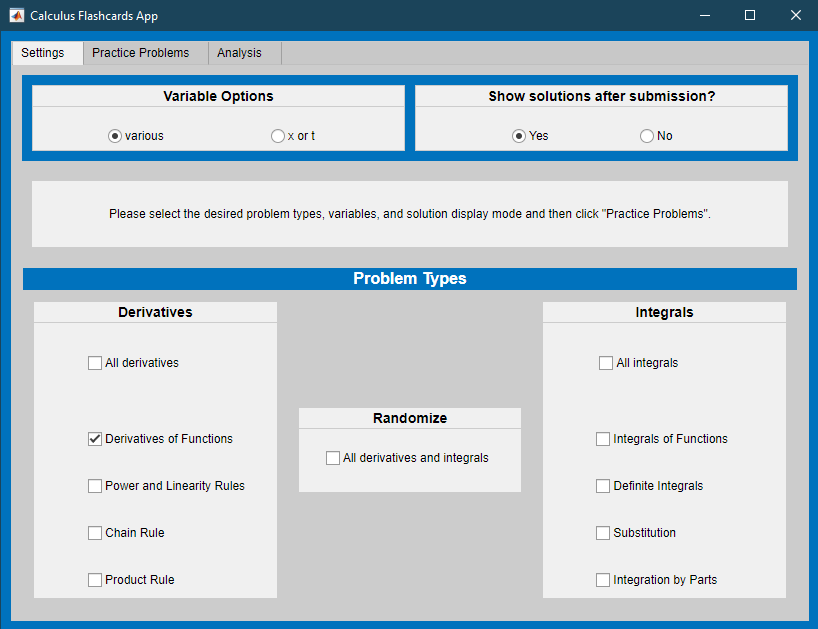](matlab: CalculusFlashcardsEs)

run("TarjetasDeCalculo")
 

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

## Funciones auxiliares locales 

 Si desea ver los detalles del código, selecciona la pestaña **View** y cambia a **Output inline**. Como alternativa, seleccionae** Output inline** usando el ícono   en la parte superior derecha del panel del Live Editor. 

function [m,linApprox] = GetLinApprox(y,x,a)
% getLin Aprox crea una función de recta tangente a y(x) en el punto x=a
%
% getLin Aprox requiere cuatro argumentos
% y una función simbólica
% x la variable independiente
% a el punto de tangencia
% getLin Aprox devuelve dos valores
% m es la pendiente como un doble
% linAprox es la recta tangente a y(x) en x=a como symfun
dy = diff(y,x);         % Calcular simbólicamente thivative y'(x)
m = subs(dy,x,a);       % Calcular simbólicamente la pendiente m = y'(a)
ya = subs(y,x,a);       % Calcular simbólicamente y(a)
linApprox = @(x) ya + m*(x-a);  % Calcula simbólicamente la recta tangente y = y(a) + y'(a)*(x-a)
m = double(m);          % Expresar la pendiente como un número.
end

function CheckEx1(myAnswer)
% CheckEx1 comprueba la expresión de la derivada de y=x^3
syms x
correctAnswer = 3*x^2;
if myAnswer == correctAnswer
    disp("Eso es correcto.")
else
    disp("Eso es incorrecto. Por favor, intenta de nuevo.")
end
end

function g = GetGravity(planet)
% getGravity establece la constante de aceleración g según el sistema solar
% cuerpo elegido
%
% el planeta es una cuerda
switch planet
    case "Mercurio"
        g = 3.59;
    case "Venus"
        g = 8.87;
    case "Earth"
        g = 9.81;
    case "Marte"
        g = 3.71;
    case "Júpiter"
        g = 25.95;
    case "Luna"
        g = 1.62;
    case "Saturno"
        g = 11.08;
    case "Neptuno"
        g = 14.07;
    case "Urano"
        g = 10.67;
    case "Plutón"
        g = .62;
    case "Sol"
        g = 274.13;
end
end

function [fh, tmax] = SolveParabolicMotion(planet,v0,h0)
% SolveParabolicMotion configura y grafica una parábola
%
% Entradas: el planeta es una cuerda, v0 = velocidad inicial, h0 = altura inicial
% Salidas: fh es un identificador de la ecuación parabólica, [0 tmax] son ��los xlims de
% la gráfica
syms t                             % Crear una variable simbólica t
g = GetGravity(planet);            % getGravity está definido en Funciones auxiliares locales
% getGravity establece la constante de aceleración g según el sistema solar
% cuerpo elegido
fh = @(t)-g*t.^2/2 + v0*t + h0;    % Definir un identificador de función para la parábola
if (v0 < 0) && (h0 < 0)            % Compruebe si hay valores iniciales razonables
    disp("¡Tienes que lanzar hacia arriba y estar por encima del suelo, o la pelota no viajará a ninguna parte!")
    disp("Por favor, establece valores positivos para v0 y h0 y ejecuta esto de nuevo.")
elseif v0 < 0                      % Compruebe si hay valores iniciales razonables
    disp("Deberías observar el movimiento parabólico con un ápice.")
    disp("Por favor, establece un valor positivo para v0 y ejecuta esto de nuevo.")
end
% Calcule el valor físicamente interesante de tmax
if h0 > 0
    % For positive initial height, select the most positive root of the
    % parabola -g/2*t^2 + v0*t + h0
    tmax = max(roots([-g/2,v0,h0])); %#ok<*NASGU>
else
    % For non-positive initial height, set a tmax that centers the apex if v0>0
    % This returns to the starting height at tmax
    % If v0<0, there are no physically realistic choices so the user is
    % encouraged to choose different initial values
    tmax = abs(2*v0/g);
end
fplot(fh,[0 tmax])                           % Trazar simbólicamente la parábola
formatSpec = "$h(t) = %.2ft^2 + %.2ft + %.2f$";  % Set up a format string for displaying
% información del gráfico con 2 decimales
hStr = compose(formatSpec,[-g/2 v0 h0]);     % Crea la cadena con los valores actuales.
% Etiquete la trama apropiadamente
legend(hStr,"Interpreter","latex","Location","best")
title("Movimiento Parabólico en " + planet)
xlabel("Tiempo (s)")
ylabel("Elevación (m)")
end

function CheckVelocity(vh,fh)
% CheckVelocity determina si el primer argumento es la derivada de
% el segundo argumento.
%
% checkVelocity toma dos identificadores de función como argumentos
syms t                   % Definir una variable simbólica
v(t) = vh(t);            % Crear una función simbólica desde el identificador de función
f(t) = fh(t);            % Crear una función simbólica desde el identificador de función
df(t) = diff(f,t);       % Calcular la derivada simbólica como función.
if isequal(v,df)         % Comprueba si v es la derivada de f
    disp("¡Correcto!")
else                     % Si la respuesta es incorrecta, intenta dar comentarios útiles.
    % Identificar los coeficientes de la solución.
    correctG = double(diff(f,t,2));
    correctV0 = double(df(0));
    % Check whether the answer v(t) was a linear function, i.e. with
    % constant derivative. If not, warn the user it should be linear
    try answerG = double(diff(v,t));
    catch
        warning("The derivative should be a linear function.")
        answerG = 0;
    end
    % Verifique si cada término fue correcto y brinde comentarios
    answerV0 = vh(0);
    if isequal(correctG,answerG)
        disp("Cometiste un error con el término constante.")
        disp("Por favor, revisa tu trabajo y vuelve a enviar.")
    elseif isequal(correctV0,answerV0)
        disp("Cometiste un error con el término lineal.")
        disp("Por favor, revisa tu trabajo y vuelve a enviar.")
    else
        disp("Por favor, revisa las reglas para calcular derivadas de polinomios.")
        disp("Luego corrige la respuesta y vuelve a enviar.")
    end
end
end

function CheckApexVelocity(str)
% CheckApexVelocity determina si el argumento identifica el signo de la derivada
% en el vértice de una parábola y proporciona retroalimentación
if str == "cero"
    disp("¡Correcto!")
else
    disp("Eso no es correcto. Por favor, revisa lo que sabes sobre derivadas gráficas e intenta de nuevo.")
end
end

function CheckApex(tGuess,hGuess,g,v0,h0)
% CheckApex determina si (tGuess,hGuess) es el punto vértice correcto para una parábola
% h(t) = -g/2*t^2+v0*t+h0
syms t                                      % Definir una variable simbólica
fh = @(t) -g/2*t.^2+v0*t+h0;                % Definir la parábola como un identificador de función.
if (tGuess == v0/g) && (hGuess == fh(v0/g)) % Verifique la corrección y brinde comentarios
    disp("Correcto.")
    disp("Nota: Como un tema en cálculo, puedes reemplazar algunas de las fórmulas específicas que memorizaste")
    disp("      en el pasado con reglas generales del cálculo que te permiten calcular soluciones rápidamente.")
    % Para soluciones incorrectas, intente determinar por qué la respuesta es incorrecta y brinde la retroalimentación adecuada.
elseif (tGuess == v0/g) && (hGuess ~= fh(v0/g))  % Hora correcta, altura incorrecta.
    disp("Tienes el tiempo correcto, pero la altura incorrecta.")
    disp("¿Cómo puedes evaluar la altura en un tiempo dado?")
    disp("Por favor, revisa tu trabajo y vuelve a enviar tus soluciones.")
elseif (tGuess ~= v0/g) && (hGuess == fh(v0/g))  % Altura correcta, hora incorrecta.
    disp("Tienes la altura máxima correcta, pero el tiempo incorrecto.")
    disp("Recuerda que la velocidad es cero en el ápice. ¿Cómo puedes usar eso para encontrar el tiempo?")
    disp("Por favor, revisa tu trabajo y vuelve a enviar tus soluciones.")
else                                         % No hay componentes correctos, ofrece sugerencias y sugerencias.
    disp("Tus respuestas son incorrectas. Ten en cuenta que deben ser valores exactos, por lo que puede ser más fácil trabajar en términos de g, v0 y h0.")
    disp("Recuerda que la velocidad es cero en el ápice. ¿Cómo puedes usar eso para encontrar el tiempo?")
    disp("Una vez que sepas el tiempo, ¿cómo puedes encontrar la altura en ese tiempo?")
    disp("Por favor, revisa tu trabajo y vuelve a enviar tus soluciones.")
end
tmax = double(abs(v0/g*2));  % Establecer una ventana para ver la parábola completa cuando v0>0
fplot(fh,[0, tmax])          % Traza simbólicamente la parábola en esa ventana.
ax = gca;                    % Definir un identificador de ejes
yLimits = ax.YLim;           % Extrae los límites y de la ventana.
% Aumente el límite superior y para que el vértice sea claramente visible en el gráfico.
yLimits(2) = .1*(yLimits(2)-yLimits(1))+yLimits(2);
ax.YLim = yLimits;           % Establecer los límites y en los ejes.
hold on
xline(tGuess, "r--")         % Agregue una línea vertical en el tGuess definido por el usuario
yline(hGuess, "g:")          % Agregue una línea horizontal en el hGuess definido por el usuario
% Etiquete la trama apropiadamente
title("Localizando el Ápice de una Parábola")
xlabel("t (s)")
ylabel("h (m)")
legend("Parábola", "Mi Tiempo Calculado del Ápice", "Mi Altura Calculada del Ápice", "Ubicación", "mejor")
hold off
end

function CheckPwrRule(dfdx,x,n)
% CheckPwrRule compara dfdx con la regla de potencia correcta y muestra
% comentarios
syms x n
pwrRule = n*x^(n-1);               % Defina la regla de la potencia en términos de x y n
correct = isequal(dfdx,pwrRule);   % Compruebe si dfdx es igual a pwrRule
if correct                         % correcto = 1, muestra comentarios "correctos"
    disp("¡Buen trabajo! La regla del poder es f'(x) = n*x^(n-1).")
else                               % correcto = 0, muestra comentarios "incorrectos"
    disp("No, eso no es correcto. Por favor, intenta de nuevo.")
end
end

function AnalyzeResults(totProbs,errorCount,totAttempts,adjustCount,lastFive)
% AnalyzeResults proporciona retroalimentación en el caso de un solo tipo de problema
% totProbs, errorCount, totAttempts y ajustaCount son números enteros
% lastFive es un vector
overallRight = (1 - sum(errorCount)/sum(totProbs))*100;
if sum(totAttempts) > sum(totProbs)
    % Si el usuario ha vuelto a enviar después de ver la solución, responda
    disp("¿Por qué estás reenviando después de saber la solución?")
    disp("Los reenvíos no se incluyen en tus estadísticas.")
    if adjustCount > 1
        % Si el usuario está reenviando repetidamente, animarlo a usar
        % este generador de problemas como se pretende, comenzando de nuevo
        disp("Has reenviado "+sum(adjustCount)+" veces.")
        disp("Por favor, considera reiniciar el conteo usando el botón `Inicializar Valores'.")
    end
end
if totProbs >= 5
    lastCorrect = sum(lastFive);
    % Si se han intentado más de 5 problemas, proporcionar retroalimentación gramaticalmente
    % apropiada sobre las tasas de éxito
    if lastCorrect > 1
        str = compose("La tasa de éxito general es de %.1f%% en %i problemas totales. \n\n" + ...
            "De los últimos cinco, %i fueron correctos.", overallRight, totProbs, lastCorrect);
    elseif lastCorrect == 1
        str = compose("La tasa de éxito general es de %.1f%% en %i problemas totales. \n\n" + ...
            "De los últimos cinco, uno fue correcto.", overallRight, totProbs);
    elseif lastCorrect == 0
        str = compose("La tasa de éxito general es de %.1f%% en %i problemas totales. \n\n" + ...
            "De los últimos cinco, ninguno fue correcto.", overallRight, totProbs);
    end
else
    % Si se han intentado menos de 5 problemas, fomente la perseverancia.
    if totProbs == 1
        str = compose("La tasa de éxito general es de %i%% en un solo problema. \n\n" + ...
            "Por favor, haz al menos cinco problemas.", overallRight);
    else
        str = compose("La tasa de éxito general es de %.1f%% en %i problemas totales. \n\n" + ...
            "Por favor, haz al menos cinco problemas.", overallRight, totProbs);
    end
end
disp(str)
end

function [lastFive,errorCount] = Check1(myFunc,myVar,myAnswer,errorCount,lastFive)
% Check1 genera respuestas correctas al diferenciar y actualizar
% errorCount y lastFive
%
% Entradas: myFunc es la función simbólica para diferenciar 
% o integrar myVar es la variable independiente myAnswer es 
% la función o número de prueba simbólico errorCount es un número 
% entero que rastrea el total de intentos incorrectos *-- -* 
% lastFive es un vector que rastrea los últimos cinco intentos 
% Salida: correctAnswer es una función simbólica que es la solución 
% a probType aplicada a myFunc(myVar) con bds
syms C
correctAnswer = diff(myFunc,myVar);
lastFive(1:4) = lastFive(2:5);
disp("Cuando se simplifica, esta función es: ")
disp(myAnswer)
if correctAnswer == myAnswer
    disp("Esa respuesta es correcta.")
    lastFive(5) = 1;
else
    disp("Eso es incorrecto. La respuesta correcta es:")
    correctAnswer %#ok<NOPRT>
    errorCount = errorCount + 1;
    disp("Por favor, intenta de nuevo con un nuevo problema.")
    lastFive(5) = 0;
end
end

function [myFun,varChoice] = GenProdType(varOpts,probType)
% GenProdType configura una variable y genera una función aleatoria
%
% Entradas: varOpts es una matriz de posibles variables
% probType es una cadena que identifica el tipo de función
% Salidas: myFun es una función simbólica
% varChoice es la variable independiente
% probType es un número entero que rastrea el tipo de pregunta formulada
% [a, b] son ��los límites de la integral definida, si es necesario

% Seleccione aleatoriamente una variable del conjunto varOpts
varChoice = varOpts(randi([1 length(varOpts)],1));

% Utilice GenFunDiff para generar funciones simples
% GenFunDiff se define en Funciones auxiliares locales
% Las entradas a GenFunDiff son la variable varChoice, un rango de valores
% entre los cuales seleccionar coeficientes y un valor que indica qué advertencias
% ya se han impreso durante la generación del problema
switch probType
    case 1 % derivada simple
        myFun = GenFunDiff(varChoice,[1,10]);  % Generar miDiversión
        % Mostrar el problema de derivada
        disp("Toma la derivada con respecto a: ")
        disp(varChoice)
        disp(" de la función ")
        displayFormula("f(varChoice) = myFun")
end
end

function [myFun,type] = GenFunDiff(var,bds)
% GenFunDiff genera una función aleatoria con una derivada simple
%
% Entradas: var es la variable independiente bd
% s es un vector 1x2 de valores enteros crecientes 
% que establece el rango para los coeficientes prevType 
% es un número entero que identifica el tipo de 
% función *- --* creado por última vez Salidas: 
% myFun es la función simbólica generada
syms f(t)                   % Crear una función simbólica f(t)
params = randi(bds,[1 5]);  % Elija aleatoriamente los valores de los parámetros
sgns = randi([0 1],[1 3]);  % Elija aleatoriamente signos +/-
type = randi([1 6],1);     % Elija aleatoriamente el tipo de función

% Para facilitar la lectura, cree los parámetros a,b,c yd.
a = (-1)^sgns(1)*params(1);
b = (-1)^sgns(2)*params(2);
c = max(params(3),params(5));  % c > 0, solo se usa como denominador
d = (-1)^sgns(3)*params(4);

switch type
    case 1
        f(t) = a*t^(b);
    case 2
        f(t) = a*t^(b/c);
    case 3
        f(t) = a*t^b+c*t^d;
    case 4
        f(t) = a*t^b+t^(d/c);
    case 5
        f(t) = t^a+c*t^b+t^d;
    case 6
        f(t) = t^a+c*t^b+d;
end

myFun = f(var);
end

function [lastFive,errorCount,totAttempts,adjustCount] = ResubmissionCheck(totAttempts,totProbs, ...
    adjustCount,myFun,varChoice,myAnswer,probType,errorCount,lastFive)
if sum(totAttempts > (totProbs + adjustCount))
    % Check if this is a resubmission after the solution has been provided
    % If so, provide feedback but do not record in errorCount or lastFive
    % If not, update the values of lastFive and errorCount using check1
    adjustCount = totAttempts-totProbs;
    if length(totProbs)>1
        [lastFive,errorCount] = check(myFun,varChoice,myAnswer,probType,errorCount,lastFive);
    else
        [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);
    end
elseif sum(totAttempts < (totProbs + adjustCount))
    % Check if this is a submission after the generation of multiple problems that were skipped
    % If so, add the skipped problems to errorCount and adjust the totAttempts
    % to compensate. Explain to the user that skipped problems count as incorrect.
    numSkipped = totProbs + adjustCount - totAttempts;
    errorCount = errorCount + numSkipped;
    totAttempts = totProbs + adjustCount;
    for k = 1:length(totProbs)
        if numSkipped(k) < 5
            lastFive(k,:) = [lastFive(k,1+numSkipped:5),zeros(1,numSkipped)];
        else
            lastFive(k,:) = zeros(1,5);
        end
        if sum(numSkipped) > 1
            disp("Los "+sum(numSkipped)+" problemas generados sin intentos de solución " + ...
                "han sido incluidos en el conteo de errores.")
            disp(" ")
        elseif sum(numSkipped) == 1
            disp("El problema generado sin un intento de solución ha sido " + ...
                "incluido en el conteo de errores.")
        end
        if length(totProbs) > 1
            [lastFive,errorCount] = check(myFun,varChoice,myAnswer,probType,errorCount,lastFive);
        else
            [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);
        end
    end
else
    if length(totProbs) > 1
        [lastFive,errorCount] = check(myFun,varChoice,myAnswer,probType,errorCount,lastFive);
    else
        [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);
        % check1 is defined in Local Helper Functions
        % check1 generates correct answers by differentiating myFun with respect to varChoice and compares
        % the result to myAnswer before updating the integer errorCount and matrix lastFive
    end
end
end
